## Import

 
% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "Time_s_", "IntensityCh1"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

[file, folder] = uigetfile('*.txt');
fullfile(folder, file)

ans = 'U:\Projekte an Analysis1\Hannah\LSM Data\230914_Ca-Imaging\vCMC_Myh6-Piezo1-m_Tam+_stT_2mMCa_S03Z01L01-4.txt'

% Import the data
tbl = readtable(fullfile(folder, file), opts);

% Clear temporary variables
clear opts

% Display results
tbl

tbl = 65107×3 table
    Time     Time_s_     IntensityCh1
    ____    _________    ____________

      1             0       43.971   
      2     0.0009216       41.809   
      3     0.0018432       41.584   
      4     0.0027648       44.787   
      5     0.0036864       45.137   
      6      0.004608       40.186   
      7     0.0055296       45.148   
      8     0.0064512       44.629   
      9     0.0073728       44.779   
     10     0.0082944       43.254   
     11      0.009216       41.193   
     12      0.010138        41.58   
     13      0.011059       41.707   
     14      0.011981       42.771   
     15      0.012902       40.496   
     16      0.013824       44.137   


## Cleanup and Prep.

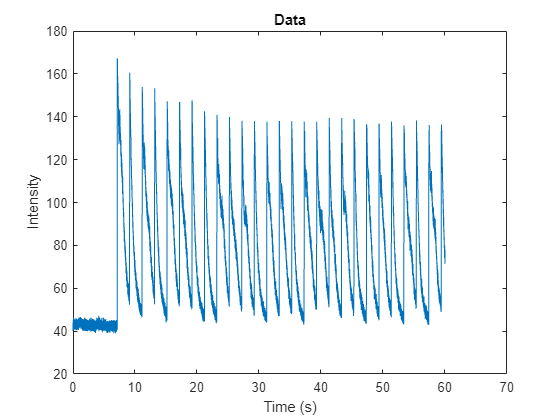

 
tbl=tbl(~any(ismissing(tbl),2),:);
tbl = tbl(:,2:3);
tbl.Properties.VariableNames = {'Time', 'Intensity'};
plot(tbl.Time, tbl.Intensity)
title("Data")
xlabel("Time (s)")
ylabel("Intensity")

## Smooth

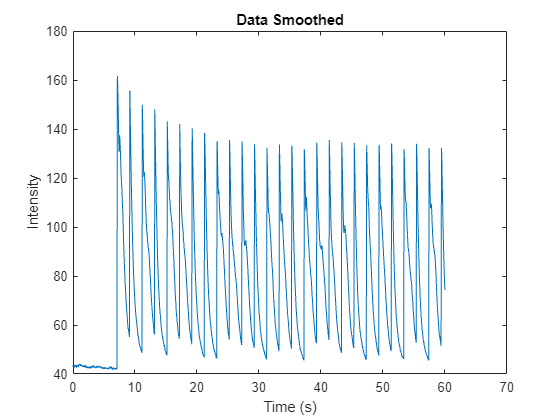

 
tbl = smoothdata(tbl,"movmedian",50,"DataVariables","Intensity");
plot(tbl.Time, tbl.Intensity)
title("Data Smoothed")
xlabel("Time (s)")
ylabel("Intensity")

Time = tbl.Time;
Intensity = tbl.Intensity;

## Find Peaks

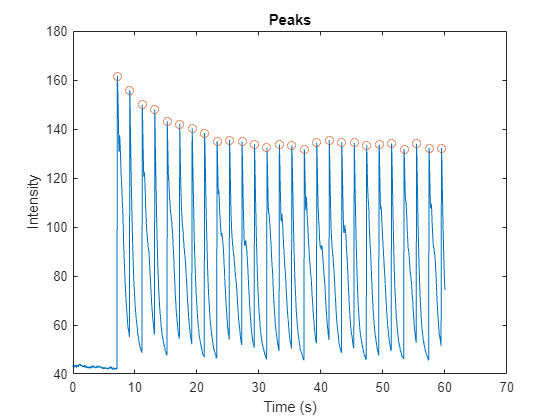

 
MinPeakProminence = 10;
MinPeakDistance = 1;
[pks,timePeak] = findpeaks(Intensity, Time ,'MinPeakProminence',MinPeakProminence,'MinPeakDistance', MinPeakDistance); %Prominence: https://de.mathworks.com/help/signal/ug/prominence.html
peakInterval = diff(timePeak);
plot(Time,Intensity, timePeak,pks,'o')
xlabel('Time (s)')
ylabel('Intensity')
title("Peaks")

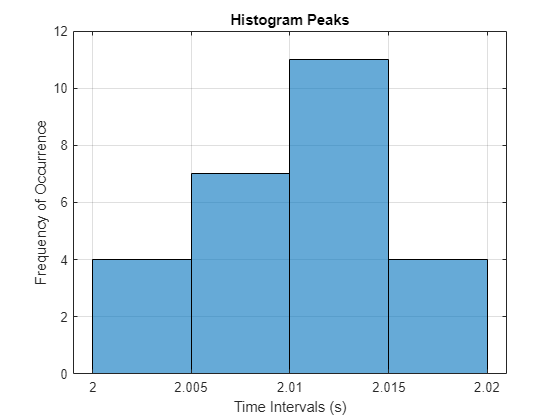

histogram(peakInterval)
title("Histogram Peaks")
grid on
xlabel('Time Intervals (s)')
ylabel('Frequency of Occurrence')

AverageDistance_Peaks = mean(diff(timePeak))

AverageDistance_Peaks = 2.0104

baselineDistance = -1.3;
for i = 1: numel(timePeak)
    [~, ix5] = min(abs(Time - (timePeak(i)-0.3)));
    [~, ix6] = min(abs(Time - (timePeak(i)+baselineDistance)));
    baseline(i) = median(Intensity(ix6:ix5));
end

## Fit

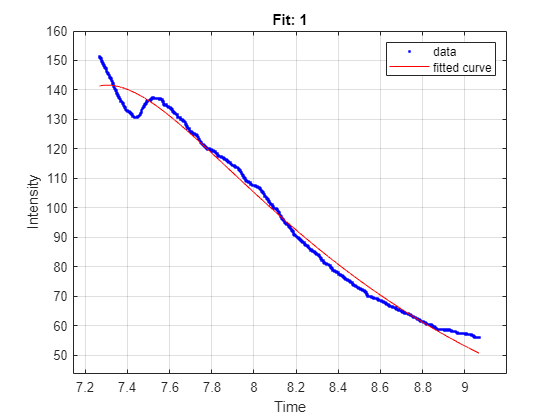

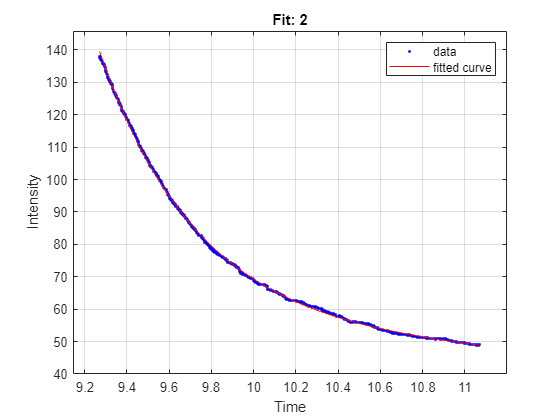

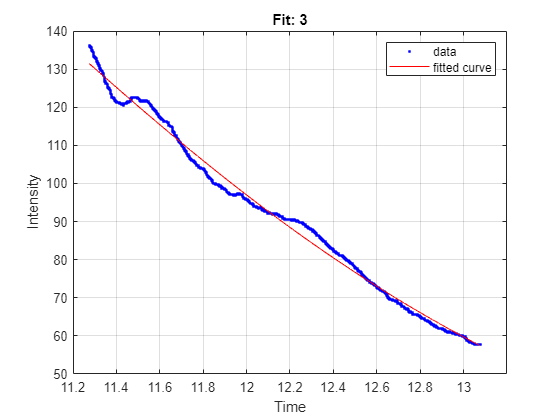

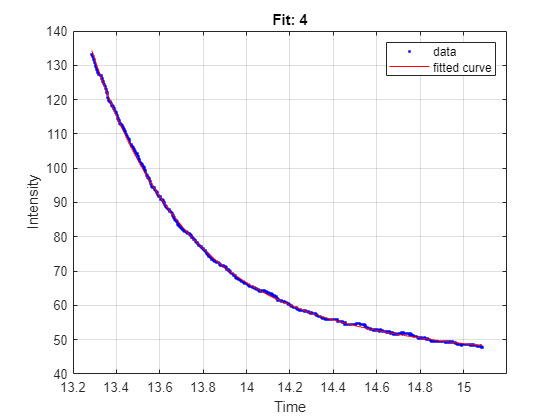

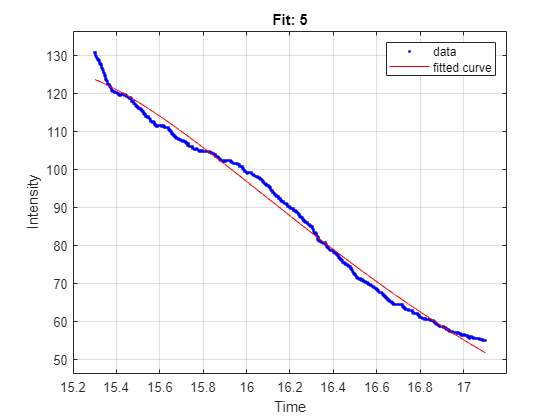

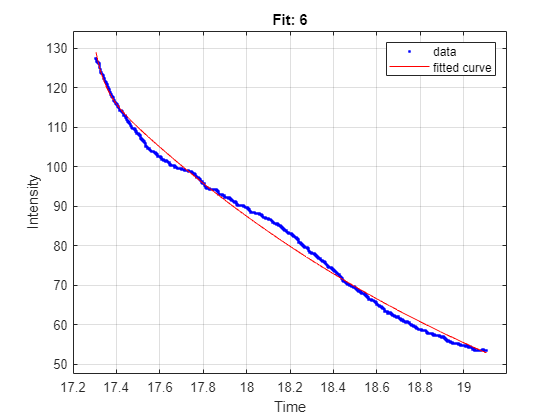

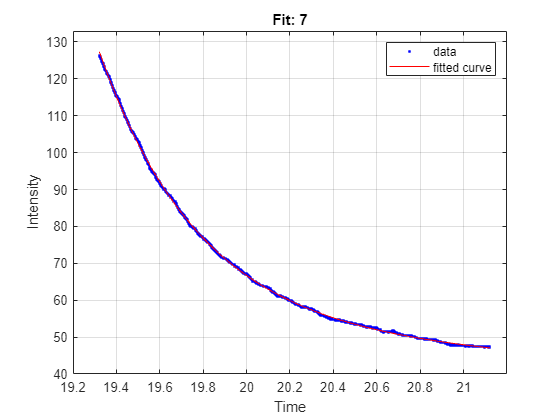

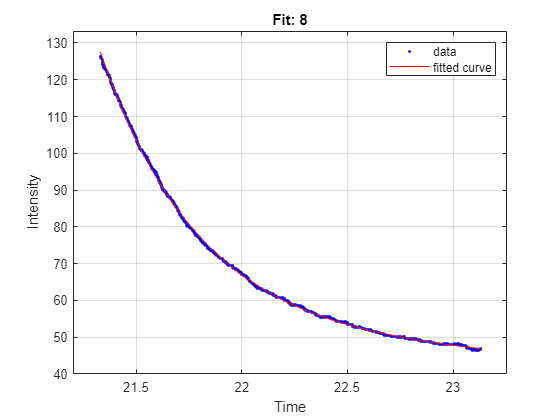

 
fitDistance = 1.9;
for i = 1: numel(timePeak)
    [~, ix1] = min(abs(Time - (timePeak(i)+0.1)));
    [~, ix2] = min(abs(Time - (timePeak(i)+fitDistance)));
    TimeFit = Time(ix1:ix2);
    IntensityFit = Intensity(ix1:ix2);
    [fitresult, gof] = createFit(TimeFit, IntensityFit);
    title(append("Fit: ", num2str(i)));
    axis padded
    tauFast = log(1/2) / fitresult.b;
    tauSlow = log(1/2) / fitresult.d;
    gof.tauSlow = tauSlow;
    gof.tauFast = tauFast;
    fitData(i) = struct('fit', fitresult, 'fitInfo', gof, 'Intensity', IntensityFit, 'Time', TimeFit);
end

## Taus

 
"T1/2 Slow"

ans = "T1/2 Slow"

for i = 1: numel(timePeak)
    slowTaus(i) = fitData(i).fitInfo.tauSlow;
    append(num2str(i),": ", num2str(slowTaus(i)))

end

ans = "1: 1.8764"

ans = "2: 13.5247"

ans = "3: 1.827"

ans = "4: 16.5511"

ans = "5: 1.3751"

ans = "6: 2.9273"

ans = "7: 19.1798"

ans = "8: 19.6552"

ans = "9: 1.4591"

ans = "10: 3.3033"

ans = "11: 3.0606"

ans = "12: 51.6594"

ans = "13: 2.4185"

ans = "14: 2.3525"

ans = "15: 20.2703"

ans = "16: 2.5545"

ans = "17: 3.7532"

ans = "18: 2.728"

ans = "19: 1.4374"

ans = "20: 20.838"

ans = "21: -0.41683"

ans = "22: 2.4495"

ans = "23: 28.0128"

ans = "24: 2.102"

ans = "25: 44.6061"

ans = "26: 1.4173"

ans = "27: -0.49229"

"T1/2 Fast"

ans = "T1/2 Fast"


for i = 1: numel(timePeak)
    fastTaus(i) = fitData(i).fitInfo.tauFast;
    append(num2str(i),": ", num2str(fastTaus(i)))
end

ans = "1: 0.38325"

ans = "2: 0.60495"

ans = "3: 1.8272"

ans = "4: 0.5753"

ans = "5: 1.3752"

ans = "6: 0.05526"

ans = "7: 0.61715"

ans = "8: 0.61921"

ans = "9: 1.459"

ans = "10: 0.07796"

ans = "11: 0.054039"

ans = "12: 0.62304"

ans = "13: 0.35519"

ans = "14: 0.54519"

ans = "15: 0.58099"

ans = "16: 0.45443"

ans = "17: 0.051603"

ans = "18: 0.097551"

ans = "19: 1.4371"

ans = "20: 0.56313"

ans = "21: 2.0676"

ans = "22: 0.27086"

ans = "23: 0.57129"

ans = "24: 2.102"

ans = "25: 0.57405"

ans = "26: 1.4175"

ans = "27: 4.2676"

append("Median Tau1/2 Slow: ", num2str(median(slowTaus)), " +- ", num2str(std(slowTaus)))

ans = "Median Tau1/2 Slow: 2.728 +- 13.7067"

append("Median Tau1/2 Fast: ", num2str(median(fastTaus)), " +- ", num2str(std(fastTaus)))

ans = "Median Tau1/2 Fast: 0.5753 +- 0.9135"

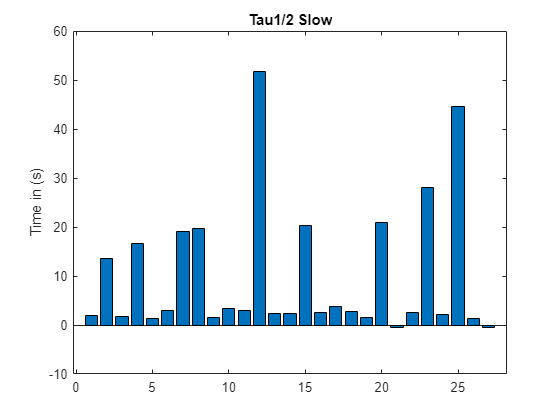


figure;bar(slowTaus)
title("Tau1/2 Slow")
ylabel("Time in (s)")

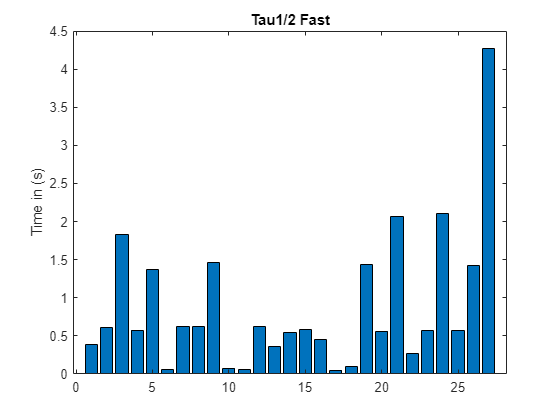

figure;bar(fastTaus)
title("Tau1/2 Fast")
ylabel("Time in (s)")

## Time To

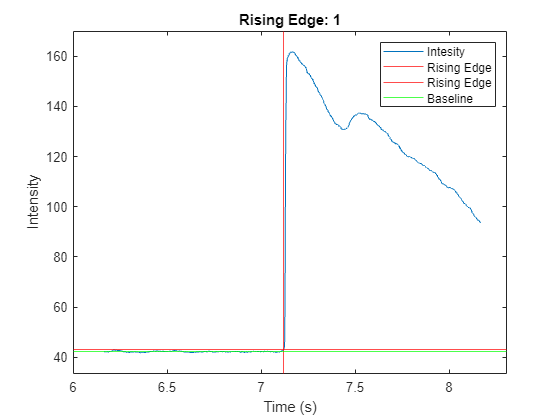

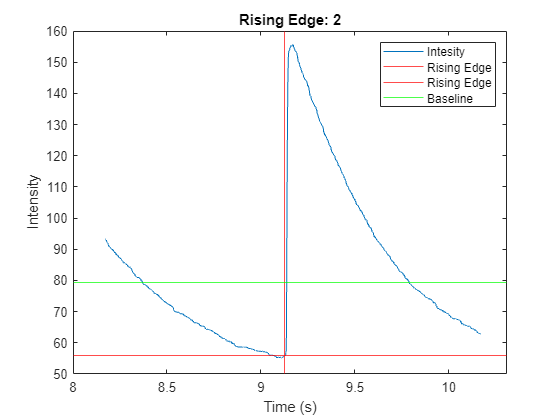

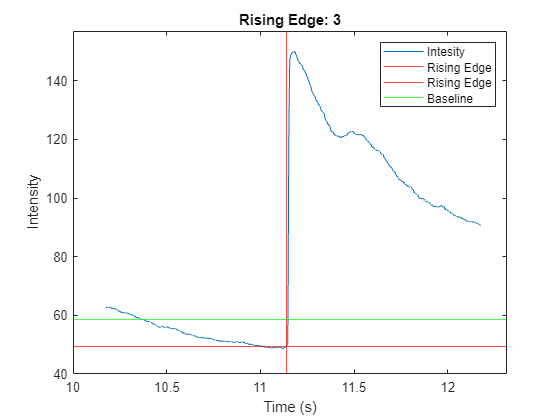

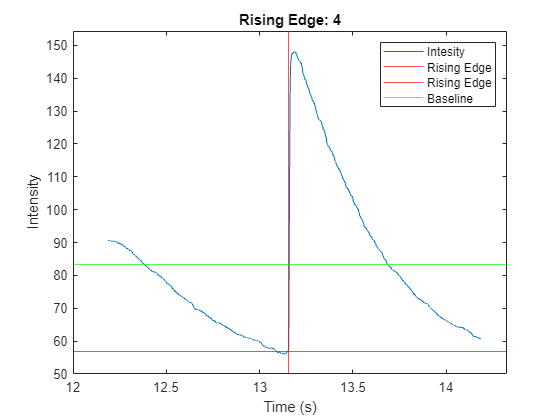

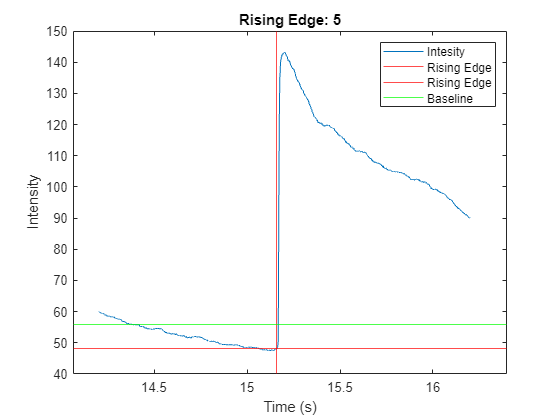

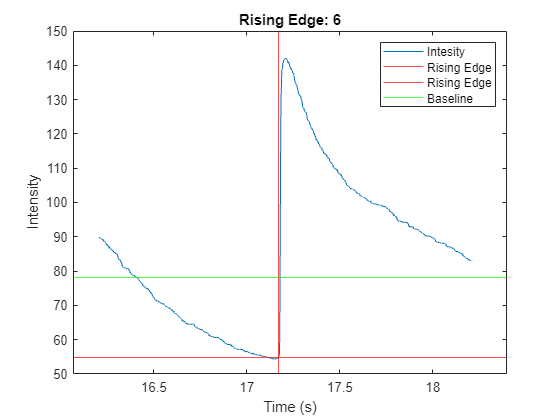

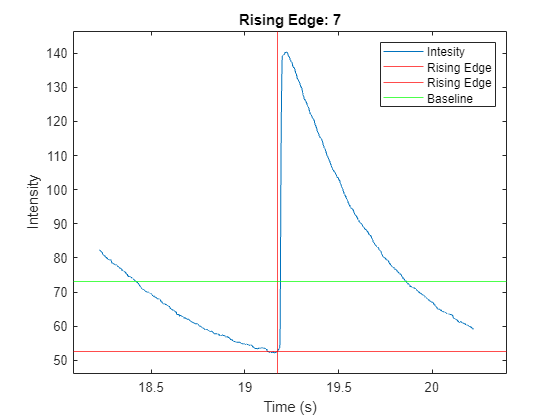

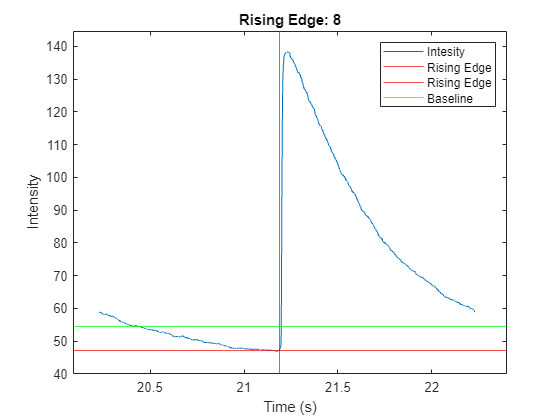

 
timeToVecStr ="25;50;75;90;100"; %Seperate Values by semicolon ;
splitStr = strsplit(timeToVecStr, ';');
timeToVec = arrayfun(@str2num,splitStr);
timeToTable = table('Size',[0,5],'VariableTypes', repelem("double",numel(splitStr)), 'Variablenames',append("Time to: ",splitStr, " (ms)"));
for i = 1: numel(timePeak)
    [~, ix3] = min(abs(Time - (timePeak(i)-1)));
    [~, ix4] = min(abs(Time - (timePeak(i)+1)));
    TimeTimeToCalc = Time(ix3:ix4);
    IntensityTimeToCalc = Intensity(ix3:ix4);
    try
        g = gradient(IntensityTimeToCalc, diff(TimeTimeToCalc(1:2)));
        ipt = findchangepts(g,'Statistic',"std");
        figure;
        plot(TimeTimeToCalc, IntensityTimeToCalc);
        title(append("Rising Edge: ", num2str(i)));
        xlabel("Time (s)")
        ylabel("Intensity")
        axis padded
        xline(TimeTimeToCalc(ipt), 'Color', 'red');
        yline(IntensityTimeToCalc(ipt), 'Color', 'red');
        yline(baseline(i), 'Color' , 'green');
        legend({'Intesity','Rising Edge','Rising Edge', 'Baseline'});
        IntensityTimeToCalc = 100 * normalize(IntensityTimeToCalc,  "range");
        IntensityTimeToCalc = IntensityTimeToCalc(ipt:find(timePeak(i) == TimeTimeToCalc));
        TimeTimeToCalc = TimeTimeToCalc(ipt:find(timePeak(i) == TimeTimeToCalc));
        [~,closestIndex] =  min(abs(IntensityTimeToCalc-timeToVec));
        timeToTable(i,:) = array2table((TimeTimeToCalc(closestIndex)-TimeTimeToCalc(1))');
    catch
        timeToTable(i,:) = table(NaN);
    end

end


timeToTable

timeToTable = 27×5 table
    Time to: 25 (ms)    Time to: 50 (ms)    Time to: 75 (ms)    Time to: 90 (ms)    Time to: 100 (ms)
    ________________    ________________    ________________    ________________    _________________

        0.009216            0.011059            0.012902            0.015667            0.048845     
        0.009216            0.011059            0.013824            0.016589            0.042394     
       0.0073728            0.009216            0.011981            0.014746            0.035021     
       0.0055296           0.0073728            0.009216            0.011059            0.033178     
       0.0082944            0.010138            0.011981            0.014746             0.04055     
       0.0082944            0.010138            0.012902            0.015667            0.

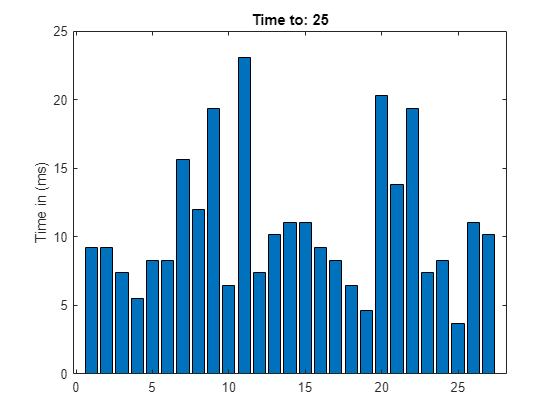

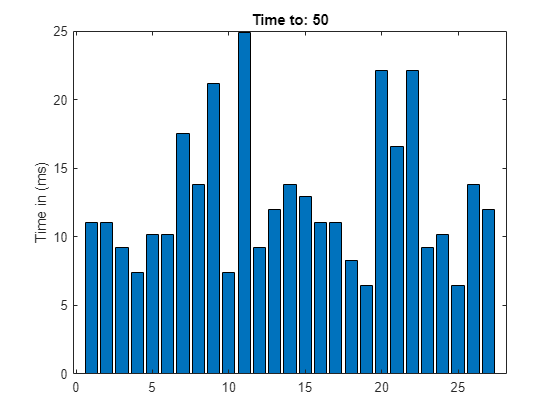

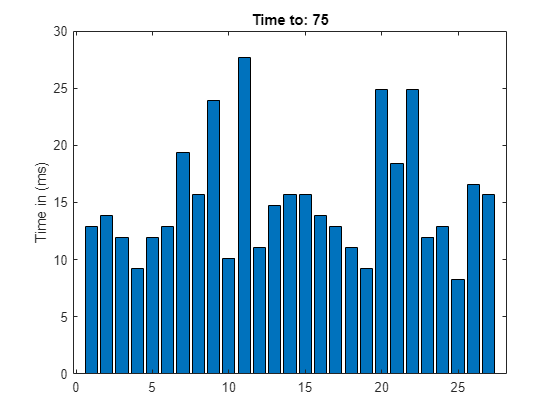

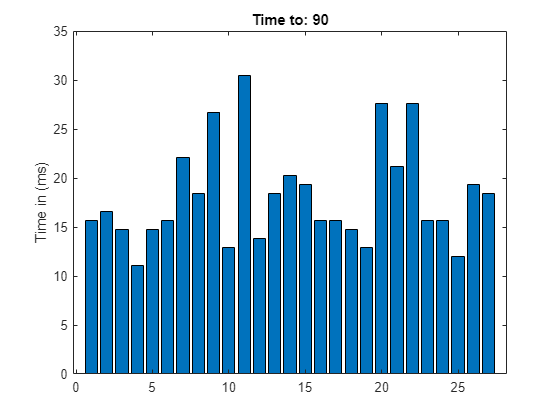

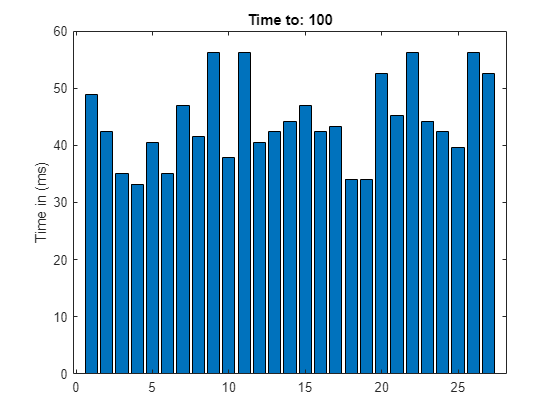


for i = 1:numel(timeToVec)
    figure;bar(timeToTable{:,i}*1000)
    title(append("Time to: ", splitStr(i)))
    ylabel("Time in (ms)")
end

## Data

 
dataTable = table(fastTaus', slowTaus', pks, baseline', pks - baseline', pks ./ baseline', timePeak);
dataTable.Properties.VariableNames ={'FastTau1/2 (s)', 'SlowTau1/2 (s)', 'Peak Intensity', 'Baseline Intensity', 'Peak Intensity Abs','F/F0' ,'Peak Time (s)'};
dataTable = [dataTable timeToTable];
dataTable

dataTable = 27×12 table
    FastTau1/2 (s)    SlowTau1/2 (s)    Peak Intensity    Baseline Intensity    Peak Intensity Abs     F/F0     Peak Time (s)    Time to: 25 (ms)    Time to: 50 (ms)    Time to: 75 (ms)    Time to: 90 (ms)    Time to: 100 (ms)
    ______________    ______________    ______________    __________________    __________________    ______    _____________    ________________    ________________    ________________    ________________    _________________

        0.38325           1.8764            161.63              42.296                119.33          3.8214     

## Save .Mat

 
uisave

## Save .csv

 
[folder, file] = uiputfile('*.csv')

folder = 'vCMC_Myh6-Piezo1-m_Tam+_stT_2mMCa_S03Z01L01-4.csv'

file = 'U:\Projekte an Analysis1\Christian\Matlab_for_everybody\Calcium Transients\'

writetable(dataTable, fullfile(file,folder))


## Save .html


 
[folder, file] = uiputfile('*.html')

folder = 'vCMC_Myh6-Piezo1-m_Tam+_stT_2mMCa_S03Z01L01-4.html'

file = 'U:\Projekte an Analysis1\Christian\Matlab_for_everybody\Calcium Transients\'

export("AnalyseSparks.mlx",fullfile(file,folder),Format="html", OpenExportedFile=true, HideCode=true)

ans = 'U:\Projekte an Analysis1\Christian\Matlab_for_everybody\Calcium Transients\vCMC_Myh6-Piezo1-m_Tam+_stT_2mMCa_S03Z01L01-4.html'